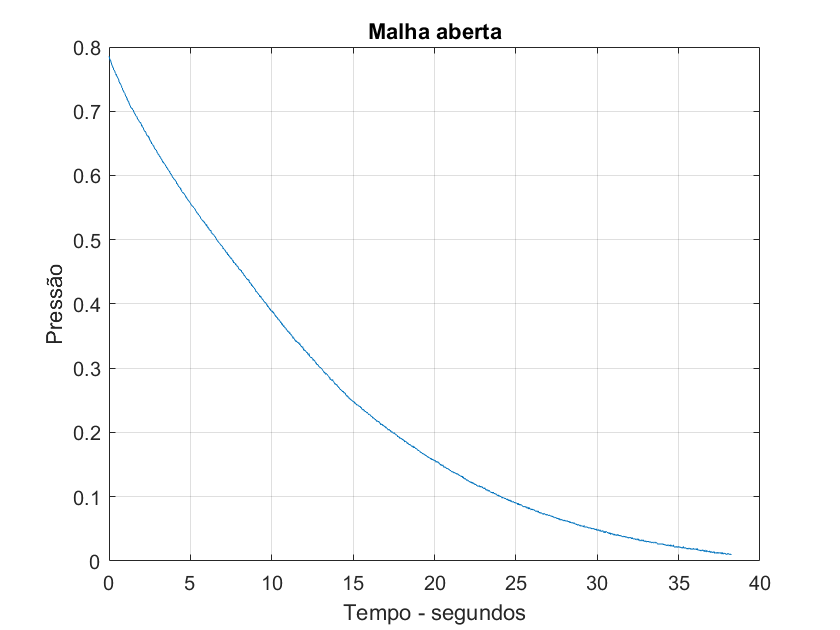

RT030_SetCompressorVoltage(0);
i=1;
pressao=0.8;
tic
while(pressao>0.01)
    pressao=RT030_GetPressure();
    lista(:,i)=pressao;
    i=i+1;
end
time = toc;

t=linspace(0,time,length(lista));

figure
plot(t,lista)
title("Malha aberta");
xlabel("Tempo - segundos")
ylabel("Pressão")
grid on;